clear;

matFile = '/Users/fraper/Documents/Desaturation_Dry/Data_Analysis/CombinedTimeTables.mat';
% List variables in file
fileInfo = whos('-file', matFile);
varNames = {fileInfo.name};

[selectedIndex, ok] = listdlg('PromptString', 'Select a variable:', ...
                              'SelectionMode', 'single', ...
                              'ListString', varNames);
if ~ok
    disp('User canceled variable selection.');
    return;
end

codename = varNames{selectedIndex};
disp(['Loading variable: ', codename]);

Loading variable: AT23NM



% Load the variable directly into workspace
evalin('base', sprintf('load(''%s'', ''%s'');', matFile, codename));

data = load(matFile, codename);
ATData = data.(codename);
% Initialize a structure to store results

Results = table();
%extract respiratory data
Resp = ATData(:,"Resp");
% Extract Mark from ATData and find event indices
ismember('Mark', ATData.Properties.VariableNames);
        Mark = ATData.Mark;
        idx = find(diff([0; Mark]) == 1); % Find one-digit increments
% Extract Mark from ATData and find event indices
if length(idx) < 6
        ismember('Mark_Life', ATData.Properties.VariableNames);
    Mark = ATData.Mark_Life;
    idx = find(Mark == 5); % Assuming 5 is the correct event marker in Mark_Life
end
% remove missing values or nan
% Remove missing data
cleaned_Resp = rmmissing(Resp);
% 1. Remove baseline ondulations using a high-pass filter
% Define high-pass filter parameters (adjust cutoff frequency based on your data)
fs = 50;  % Sampling frequency (Hz) - Adjust as needed
samples_30s = 30 * fs; % number of samples in 30 seconds
cutoff_freq = 0.1;  % Cutoff frequency for high-pass filter (Hz)
signal_data = table2array(cleaned_Resp(:,"Resp"));

% Design high-pass filter using a butterworth filter
[b, a] = butter(2, cutoff_freq / (fs / 2), 'high');  % 2nd order filter
filtered_signal = filtfilt(b, a, signal_data);  % Apply the filter

% 2. Remove the baseline by subtracting the mean (or use a moving average)
baseline_signal = mean(filtered_signal(1:30));  % Use the first 30 seconds to estimate the baseline
centered_signal = filtered_signal - baseline_signal;  % Subtract baseline

% 3. Optionally, normalize the signal (if needed)
normalized_signal = (centered_signal - min(centered_signal)) / (max(centered_signal) - min(centered_signal));

%Extract apnea segments
 A1 = normalized_signal(idx(1):idx(2),:);
 A2 = normalized_signal(idx(3):idx(4),:);
 A3 = normalized_signal(idx(5):idx(6),:);

 % Compute baseline and IBM thresholds for each apnea segment
easy_phase_A1 = A1(1:samples_30s);  % First 30s of A1
easy_phase_A2 = A2(1:samples_30s);  % First 30s of A2
easy_phase_A3 = A3(1:samples_30s);  % First 30s of A3

% Calculate baseline mean and standard deviation for each segment
baseline_mean_A1 = mean(easy_phase_A1);
baseline_std_A1 = std(easy_phase_A1);
baseline_mean_A2 = mean(easy_phase_A2);
baseline_std_A2 = std(easy_phase_A2);
baseline_mean_A3 = mean(easy_phase_A3);
baseline_std_A3 = std(easy_phase_A3);

% Compute the global mean of baseline and standard deviation across segments
baseline_mean_global = mean([baseline_mean_A1, baseline_mean_A2, baseline_mean_A3]);
baseline_std_global = mean([baseline_std_A1, baseline_std_A2, baseline_std_A3]);

% Define the single set of thresholds for all apnea segments
baseline_min = baseline_mean_global - 0.5 * baseline_std_global;
baseline_max = baseline_mean_global + 0.5 * baseline_std_global;
% Compute IBM thresholds for each apnea
ibm_min_A1 = baseline_mean_A1 + 0.005;  
ibm_max_A1 = baseline_mean_A1 + 3 * baseline_std_A1;

ibm_min_A2 = baseline_mean_A2 + 0.005;  
ibm_max_A2 = baseline_mean_A2 + 3 * baseline_std_A2;

ibm_min_A3 = baseline_mean_A3 + 0.005;  
ibm_max_A3 = baseline_mean_A3 + 3 * baseline_std_A3;

% Use the most inclusive thresholds across all apneas
ibm_min = min([ibm_min_A1, ibm_min_A2, ibm_min_A3]);  
ibm_max = max([ibm_max_A1, ibm_max_A2, ibm_max_A3]);  

% Use function detect_ibm to detect mathematically and visually the ibm's
final_ibm(1) = detect_ibm(A1,ibm_min,ibm_max,fs);
final_ibm(2) = detect_ibm(A2,ibm_min,ibm_max,fs);

Please select a new IBM location...


Please select a new IBM location...


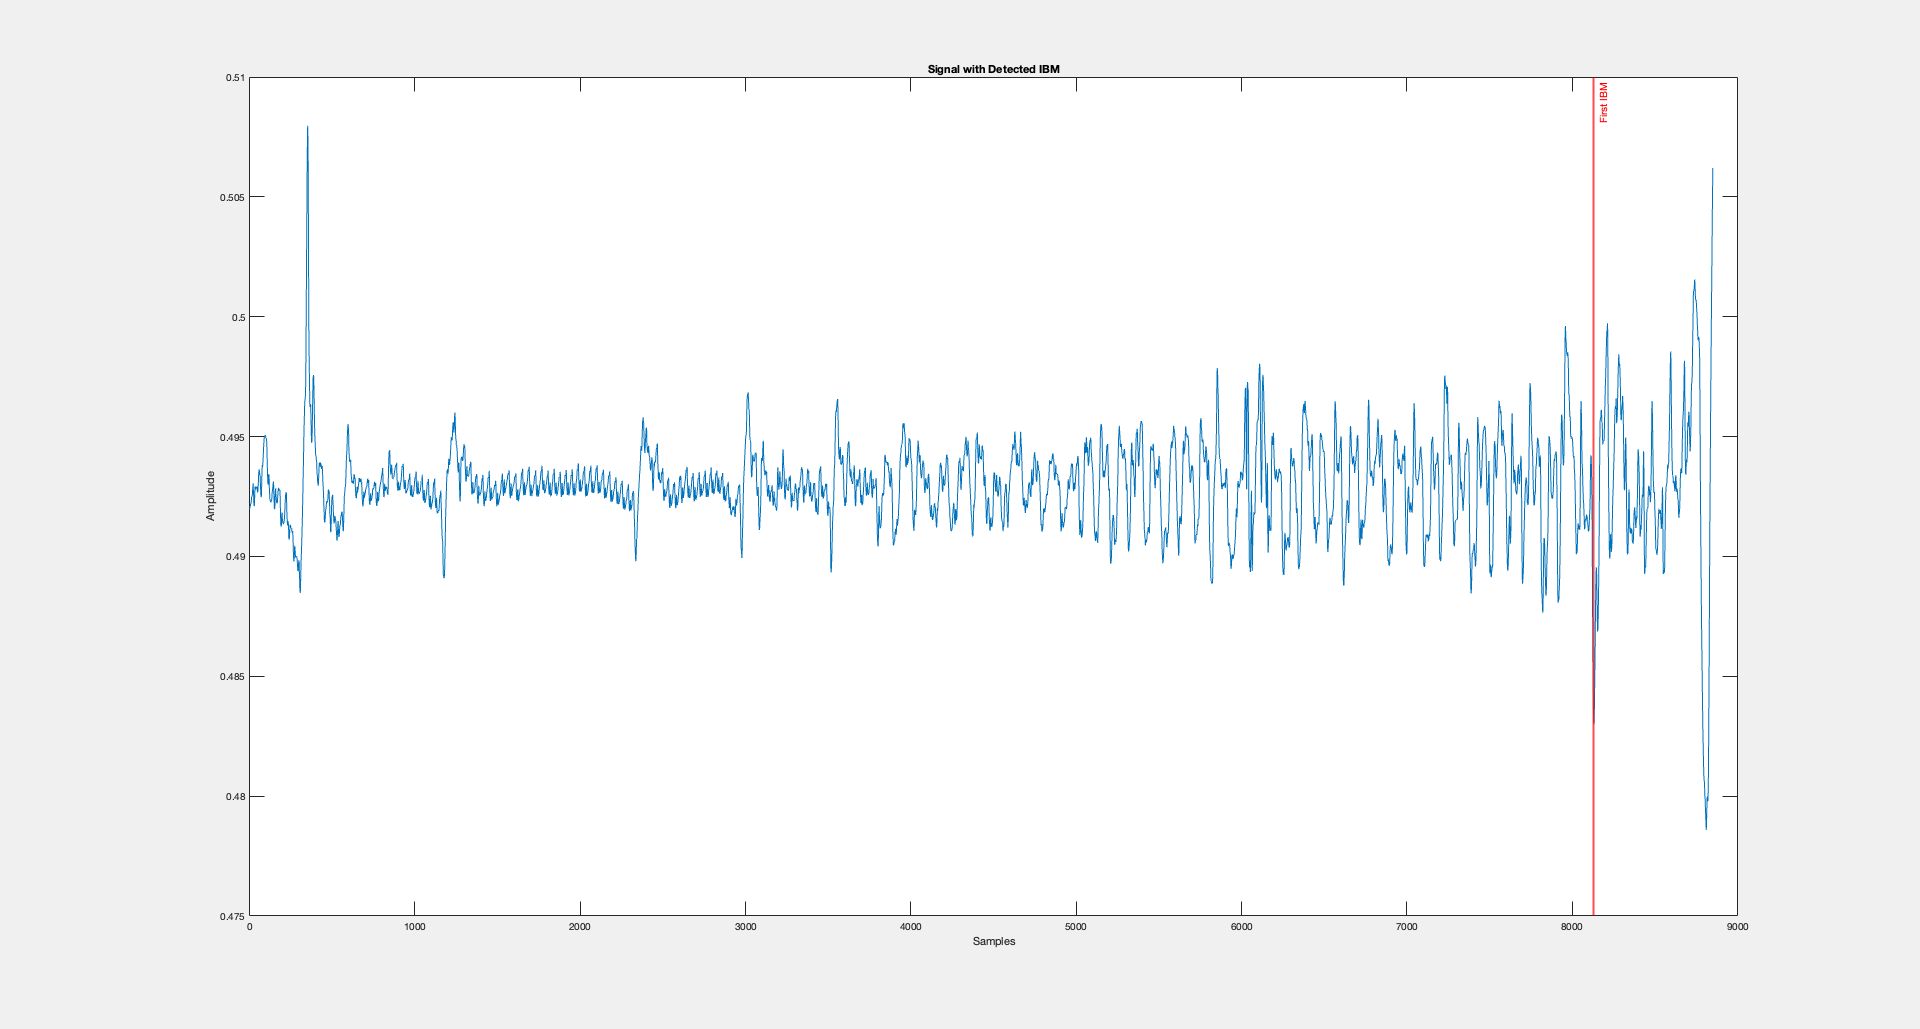

final_ibm(3) = detect_ibm(A3,ibm_min,ibm_max,fs);


tempResults = table(string(codename),final_ibm(1), final_ibm(2), final_ibm(3), ...
    'VariableNames', {'code','ibmA1', 'ibmA2', 'ibmA3'});
load ResultsIBM.mat;
% Append to Results table
    Results = [Results; tempResults];
    disp(Results);

      code      ibmA1     ibmA2     ibmA3 
    ________    ______    ______    ______

    "AT01DL"       NaN     91.21    81.912
    "AT02LC"       NaN    88.629     91.59
    "AT03VK"       NaN    88.629    118.78
    "AT04TJ"       NaN    36.435    72.345
    "AT06FM"       NaN    100.89    100.29
    "AT07TJ"       NaN       NaN    151.11
    "AT08AS"    44.185     75.76    92.608
    "AT09VM"       NaN    90.346    95.598
    "AT10DH"       NaN    91.663    109.98
    "AT11PJ"     46.02    81.032    64.684
    "AT12BA"    50.207    75.386    75.511
    "AT13CY"       NaN    47.631     96.27
    "AT14EQ"       NaN       NaN    143.01
    "AT16DK"       NaN     74.78     88.96
    "AT17MS"       NaN    81.502    95.733
    "AT18DL"       NaN    118.76    142.37
    "AT19MG"       NaN    56.005    78.308
    "AT19SD"       NaN    62.967    88.216
   

% Save results as .mat file
save('ResultsIBM.mat', 'Results')